# Inverse Kinematics

Author: Keith Chester

E-mail: kchester@wpi.edu

## Introduction

In this problem, we will be generating the inverse kinematics for the following robotic arm, and simulating its output for a given X and Y.

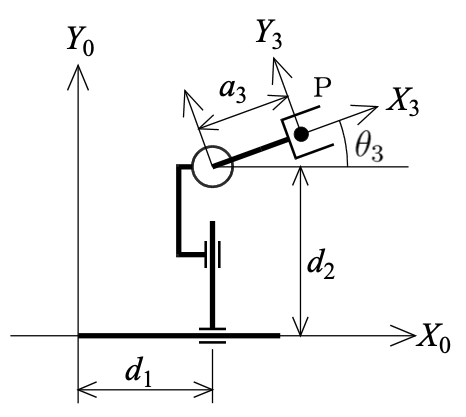

*Figure 1: The robot arm being analyzed*

## The Inverse Kinematics

Here, we can immediately build the following relationships:


$$\begin{array}{l}
x=d_1 +a_3 \mathrm{cos}\left(\theta_3 \right)\\
y=d_2 +a_3 \mathrm{cos}\left(\theta_3 \right)
\end{array}$$


We can expand the triangle formed by $\theta_3$, and, using law of cosines, also determine that


$${\left(y-d_2 \right)}^2 =a_3^2 +{\left(x-d_1 \right)}^2 -2a_3 \left(x-d_1 \right)\mathrm{cos}\left(\theta_3 \right)$$


...which, solving for $\theta_3$:


$$\theta_3 =\mathrm{acos}\left(\frac{a_3 +{\left(x-d_1 \right)}^2 -{\left(y-d_2 \right)}^2 }{2a_3 \left(x-d_{\left.1\right)} \right)}\right)$$


...which puts $\theta_3$ in the terms of $d_1$ and $d_2$. Thus we can rearrange our original equations as:


$$d_1 =a_3 \mathrm{cos}\left(\theta_3 \right)-x$$



$$d_2 =a_3 \mathrm{sin}\left(\theta_3 \right)-y$$


...and thus replace $\theta_3$ with the defined function above.


$$d_1 =a_3 \left(\frac{a_3 +{\left(x-d_1 \right)}^2 -{\left(y-d_2 \right)}^2 }{2a_3 \left(x-d_{\left.1\right)} \right)}\right)-x$$



$$d_2 =a_3 \mathrm{sin}\left(\mathrm{acos}\left(\frac{a_3 +{\left(x-d_1 \right)}^2 -{\left(y-d_2 \right)}^2 }{2a_3 \left(x-d_{\left.1\right)} \right)}\right)\right)$$


We can use the Pythaegoeran theorom to setup $d_2$ as a simpler solved value in terms of $d_1$:


$$\begin{array}{l}
a_3^2 =\sqrt{{\left(x-d_1 \right)}^2 +{\left(y-d_2 \right)}^2 }\\
d_2 =\sqrt{a_3^4 -{\left(x-d_1 \right)}^2 }
\end{array}$$


## Building the Robot Arm

We need to create a set of transformation matricies for this robotic arm such that we can determine the end-effector position for a given set of joint configurations.

From each joint to the next, we create the following transformations:


$$H_1^0 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & d_1 \\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$H_2^1 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & d_2 \\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$H_3^2 =\left\lbrack \begin{array}{cccc}
\mathrm{cos}\left(\theta_3 \right) & -\mathrm{sin}\left(\theta_3 \right) & 0 & a_3 \mathrm{cos}\left(\theta_3 \right)\\
\mathrm{sin}\left(\theta_3 \right) & \mathrm{cos}\left(\theta_3 \right) & 0 & a_3 \mathrm{sin}\left(\theta_3 \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


x = 1.4;
y = 1.8;

a3 = 1;
theta3 = 45;
d1 = 1;
d2 = 1;

H_0_1 = [1 0 0 d1; 0 1 0 0; 0 0 1 0; 0 0 0 1;]

H_0_1 =      1     0     0     1
     0     1     0     0
     0     0     1     0
     0     0     0     1


H_1_2 = [1 0 0 0; 0 1 0 d2; 0 0 1 0; 0 0 0 1;]

H_1_2 =      1     0     0     0
     0     1     0     1
     0     0     1     0
     0     0     0     1


H_2_3 = [cos(theta3) -sin(theta3) 0 a3*cos(theta3); sin(theta3) cos(theta3) 0 a3*sin(theta3); 0 0 1 0; 0 0 0 1;]

H_2_3 =     0.5253   -0.8509         0    0.5253
    0.8509    0.5253         0    0.8509
         0         0    1.0000         0
         0         0         0    1.0000



% We need the transforms from the 0 frame for each coordinate axis to
% map everything back to the same frame as the plot.
H_0_2 = H_0_1 * H_1_2

H_0_2 =      1     0     0     1
     0     1     0     1
     0     0     1     0
     0     0     0     1


H_0_3 = H_0_1 * H_1_2 * H_2_3

H_0_3 =     0.5253   -0.8509         0    1.5253
    0.8509    0.5253         0    1.8509
         0         0    1.0000         0
         0         0         0    1.0000


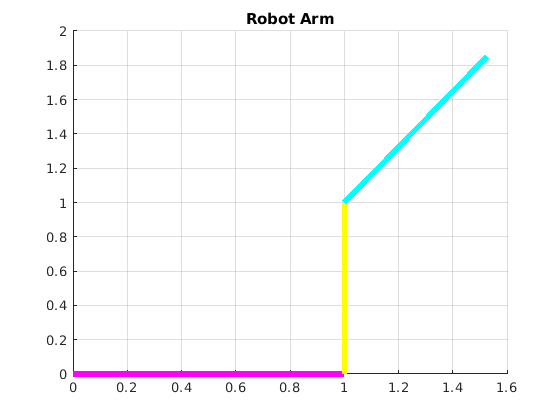


robotfigure = figure;
title("Robot Arm")
grid on
hold on
% axis([-3 3 -3 3 0 3])
% view([45 25])

% Draw coordinate axes
% [x_line, y_line, z_line] = draw_coordinate_axis(eye(4), 0.25, 'red', 'green', 'blue');
lines(end+1) = x_line;
lines(end+1) = y_line;
lines(end+1) = z_line;
% [x_line, y_line, z_line] = draw_coordinate_axis(H_0_1, 0.25, 'red', 'green', 'blue');
lines(end+1) = x_line;
lines(end+1) = y_line;
lines(end+1) = z_line;
% [x_line, y_line, z_line] = draw_coordinate_axis(H_0_2, 0.25, 'red', 'green', 'blue');
lines(end+1) = x_line;
lines(end+1) = y_line;
lines(end+1) = z_line;
% [x_line, y_line, z_line] = draw_coordinate_axis(H_0_3, 0.25, 'red', 'green', 'blue');
lines(end+1) = x_line;
lines(end+1) = y_line;
lines(end+1) = z_line;

% Draw in the limbs now
origin = [ 0; 0; 0; 1; ];
elbow = H_0_1 * origin;
wrist = H_0_2 * origin;
actuator = H_0_3 * origin;
lines(end+1) = line('XData', [origin(1) elbow(1)], 'YData', [origin(2) elbow(2)], 'ZData', [origin(3) elbow(3)], 'Color', 'magenta', 'LineWidth', 4);
lines(end+1) = line('XData', [elbow(1) wrist(1)], 'YData', [elbow(2) wrist(2)], 'ZData', [elbow(3) wrist(3)], 'Color', 'yellow', 'LineWidth', 4);
lines(end+1) = line('XData', [wrist(1) actuator(1)], 'YData', [wrist(2) actuator(2)], 'ZData', [wrist(3) actuator(3)], 'Color', 'cyan', 'LineWidth', 4);

## Functions

These functions are used to generate the above robot arm plots.

#### transform_from_dh_values

This function takes the expected DH values - $\theta$, *d*, *a*, and $\alpha$.

The use of *vargin* is used to determine if an optional parameter is passed. This optional parameter is used to determine if the caller of the function wishes to make use of symbolic values. If so, we use *cos* and *sin* instead of *cosd *and *sind* respectively. This results in slightly better outputs for symbolic functions.

function H = transform_from_dh_values(theta, d, a, alpha, varargin)
    if nargin == 4
        R_z_theta = [ cosd(theta)      -sind(theta)     0     0;
                      sind(theta)       cosd(theta)     0     0;
                      0                 0               1     0;
                      0                 0               0     1; ];
        R_x_alpha = [ 1     0               0            0;
                      0     cosd(alpha)     -sind(alpha) 0;
                      0     sind(alpha)     cosd(alpha)  0;
                      0     0               0            1; ];
    else
        R_z_theta = [ cos(theta)      -sin(theta)     0     0;
                      sin(theta)       cos(theta)     0     0;
                      0                0              1     0;
                      0                0              0     1; ];
        R_x_alpha = [ 1     0              0            0;
                      0     cos(alpha)     -sin(alpha)  0;
                      0     sin(alpha)     cos(alpha)   0;
                      0     0              0            1; ];
    end
    
    
    T_z_d = [ 1     0      0    0;
              0     1      0    0;
              0     0      1    d;
              0     0      0    1; ];
    
    T_x_a = [ 1     0      0    a;
              0     1      0    0;
              0     0      1    0;
              0     0      0    1; ];
    
    
    
    H = R_z_theta * T_z_d * T_x_a * R_x_alpha;
end

#### transform_from_dh_row

This is a helper function that takes a DH table as defined above (in the form of a cell of matricies of expected DH values in a set standard order of $\theta$, *d*, *a*, and $\alpha$. It then separates out the $\theta$, *d*, *a*, and $\alpha$ of the specified row, and passes it to **transform_from_dh_values**, as described above. The use of *vargin* is passed through, for reasons specified above.

function H = transform_from_dh_row(table, row, vargin)
    theta = table{row}(1);
    d = table{row}(2);
    a = table{row}(3);
    alpha = table{row}(4);
    if nargin == 2
        H = transform_from_dh_values(theta, d, a, alpha);
    else
        H = transform_from_dh_values(theta, d, a, alpha, true);
    end
end

#### draw_coordinate_axis

This function accepts a specified transform, length of the desired axis lines, and the color for each axis. It then draws on the current active figure the origin for that axis based on the transform passed.

function [x_line, y_line, z_line] = draw_coordinate_axis(transform, length, x_color, y_color, z_color)    
    origin = transform * [0; 0; 0; 1;];
    x = transform * [length; 0;         0;      1; ];
    y = transform * [0;      length;    0;      1; ];
    z = transform * [0;      0;         length; 1; ];
    x_line = line('XData', [origin(1) x(1)], 'YData', [origin(2) x(2)], 'ZData', [origin(3) x(3)], 'Color', x_color, 'LineWidth', 3);
    y_line = line('XData', [origin(1) y(1)], 'YData', [origin(2) y(2)], 'ZData', [origin(3) y(3)], 'Color', y_color, 'LineWidth', 3);
    z_line = line('XData', [origin(1) z(1)], 'YData', [origin(2) z(2)], 'ZData', [origin(3) z(3)], 'Color', z_color, 'LineWidth', 3);
end